clear 
clc


addpath '.\INM'
addpath '.\SD'
addpath '.\FR'
addpath '.\functions'

load('forcing_terms.mat')
load('test_functions2.mat')
load('myFunctions.mat')

%Armijo
c1 = 1e-4;
rho = 0.5;
btmax = 50;
alpha0 = 1;

%Step for finite differences
h = 1e-8;

%Problem definition
n = 1000;
x0 = x14_t(n);
f = f14;
gradf = gf14;
Hessf = 0;

kmax = 100000;
tolgrad = 1.0E-6;
toldiffgrad = 1e-12;

% max number of iterations for the pcg
pcg_maxit = 200;

run_steepest = true;
run_fr = true;
run_newton = true;



%P5 -> Converges (with tolgrad or kmax easier)
%P13 -> Converges
%P14 -> Converge (con pcgmax=200,ci mette un botto)
%P23 

##     Run Steepest Descent

if run_steepest
    disp('***Steepest Descent: start***')
    tic
    [xk_sd, fk_sd, gradfk_norm_sd, k_sd, xseq_sd, btseq_sd, fseq_sd, gfseq_sd] = ... 
        steepest_desc_bt(x0, f, gradf, alpha0, kmax, tolgrad, c1, rho, btmax)
    
    disp('***Steepest Descent: finished')
    toc
    disp('***SD: results')
    disp('*******')
    disp(['xk: ', mat2str(xk_sd)])
    disp(['f(xk): ', mat2str(fk_sd)])
    disp(['gradf(xk): ', mat2str(gradfk_norm_sd)])
    disp(['N of iterations: ', num2str(k_sd), '/', num2str(kmax), ';'])
    %epsk_steep = norm(x_star_rose-xk_sd)
    %disp(epsk_steep)
    disp('****')
else
    disp("SD Method not runned")
end

***Steepest Descent: start***


Iteration 1 gf_norm: 0.000645
Iteration 2 gf_norm: 0.000644
Iteration 3 gf_norm: 0.000644
Iteration 4 gf_norm: 0.000644
Iteration 5 gf_norm: 0.000642
Iteration 6 gf_norm: 0.000642
Iteration 7 gf_norm: 0.000641
Iteration 8 gf_norm: 0.000641
Iteration 9 gf_norm: 0.000640
Iteration 10 gf_norm: 0.000640
Iteration 11 gf_norm: 0.000640
Iteration 12 gf_norm: 0.000639
Iteration 13 gf_norm: 0.000639
Iteration 14 gf_norm: 0.000639
Iteration 15 gf_norm: 0.000639
Iteration 16 gf_norm: 0.000638
Iteration 17 gf_norm: 0.000638
Iteration 18 gf_norm: 0.000638
Iteration 19 gf_norm: 0.000638
Iteration 20 gf_norm: 0.000637
Iteration 21 gf_norm: 0.000637
Iteration 22 gf_norm: 0.000637
Iteration 23 gf_norm: 0.000637
Iteration 24 gf_norm: 0.000637
Iteration 25 gf_norm: 0.000636
Iteration 26 gf_norm: 0.000636
Iteration 27 gf_norm: 0.000636
Iteration 28 gf_norm: 0.000636
Iteration 29 gf_norm: 0.000636
Iteration 30 gf_norm: 0.000636
Iteration 31 gf_norm: 0.000636
Iteration 32 gf_norm: 0.000636
Iteration 33 gf_n

xk_sd = 1.0e-04 *

   -0.0087
   -0.0137
   -0.0162
   -0.0174
   -0.0178
   -0.0178
   -0.0178
   -0.0179
   -0.0179
   -0.0180


fk_sd = 4.4273e-09

gradfk_norm_sd = 6.3563e-04

k_sd = 100000

xseq_sd = 1.0e-04 *

   -0.0016   -0.0018   -0.0022   -0.0025   -0.0027   -0.0033   -0.0034   -0.0045   -0.0046   -0.0048   -0.0050   -0.0051   -0.0055   -0.0056   -0.0060   -0.0061   -0.0064   -0.0065   -0.0068   -0.0069   -0.0072   -0.0073   -0.0076   -0.0077   -0.0080   -0.0081   -0.0084   -0.0084   -0.0086   -0.0086   -0.0087   -0.0087   -0.0087   -0.0087   -0.0087   -0.0087   -0.0087   -0.0087   -0.0087   -0.0087   -0.0087   -0.0087   -0.0087   -0.0087   -0.0087   -0.0087   -0.0087   -0.0087   -0.0087   -0.0087
   -0.0009   -0.0017   -0.0022   -0.0028   -0.0030   -0.0040   -0.0042   -0.0060   -0.0062   -0.0065   -0.0069   -0.0071   -0.0078   -0.0080   -0.0087   -0.0088   -0.0095   -0.0096   -0.0103   -0.0104   -0.0110   -0.0112   -0.0117   -0.0119   -0.0124   -0.0126   -0.0131   -0.0132   -0.0135   -0.0136   -0.0137   -0.0137   -0.0137   -0.0137   -0.0137   -0.0137   -0.0137   -0.0137   -0.0137   -0.0137   -0.0137   -0.0137   -0.0137   -0.0137   -0.0137   -0.0137   -0.0137   -0.01

btseq_sd =      4     5     5     5     6     4     6     3     6     5     5     6     4     6     4     6     4     6     4     6     4     6     4     6     4     6     4     6     5     6     8    35    38    37    45    42    42    49    50    48    44    40    43    47    45    48    48    48    47    49


fseq_sd = 1.0e-08 *

    0.4502    0.4496    0.4493    0.4491    0.4484    0.4480    0.4477    0.4471    0.4466    0.4464    0.4462    0.4461    0.4457    0.4456    0.4453    0.4451    0.4448    0.4447    0.4444    0.4443    0.4441    0.4440    0.4437    0.4436    0.4433    0.4433    0.4430    0.4429    0.4428    0.4427    0.4427    0.4427    0.4427    0.4427    0.4427    0.4427    0.4427    0.4427    0.4427    0.4427    0.4427    0.4427    0.4427    0.4427    0.4427    0.4427    0.4427    0.4427    0.4427    0.4427


gfseq_sd = 1.0e-03 *

    0.6448    0.6439    0.6437    0.6437    0.6421    0.6418    0.6412    0.6415    0.6400    0.6398    0.6397    0.6394    0.6391    0.6389    0.6386    0.6384    0.6381    0.6379    0.6376    0.6374    0.6372    0.6370    0.6367    0.6366    0.6364    0.6362    0.6360    0.6359    0.6357    0.6356    0.6356    0.6356    0.6356    0.6356    0.6356    0.6356    0.6356    0.6356    0.6356    0.6356    0.6356    0.6356    0.6356    0.6356    0.6356    0.6356    0.6356    0.6356    0.6356    0.6356


***Steepest Descent: finished


Elapsed time is 1996.308258 seconds.


***SD: results


*******


xk: [-8.65606860254784e-07;-1.3666219119071e-06;-1.62469788307413e-06;-1.73786171949408e-06;-1.77640154063249e-06;-1.7842959888882e-06;-1.78463907698369e-06;-1.78666325476229e-06;-1.79217718258328e-06;-1.80014547110526e-06;-1.80917929086918e-06;-1.8184265263862e-06;-1.8275891694871e-06;-1.83666332531402e-06;-1.84571966567613e-06;-1.85480625972762e-06;-1.86393708967384e-06;-1.87310970231032e-06;-1.88231970650191e-06;-1.89156537132289e-06;-1.90084682831862e-06;-1.91016456957599e-06;-1.91951886351792e-06;-1.92890980716e-06;-1.93833747370548e-06;-1.94780196127636e-06;-1.95730338095972e-06;-1.96684184328289e-06;-1.97641745644839e-06;-1.98603032844587e-06;-1.99568056783568e-06;-2.00536828351721e-06;-2.01509358454874e-06;-2.0248565801746e-06;-2.03465737986548e-06;-2.04449609330227e-06;-2.05437283038642e-06;-2.0642877012042e-06;-2.07424081608166e-06;-2.08423228555007e-06;-2.09426222034739e-06;-2.10433073143008e-06;-2.11443792996745e-06;-2.12458392734369e-06;-2.13476883514761e-06;-2.14499276519

f(xk): 4.4272617144113e-09


gradf(xk): 0.000635632144050344


N of iterations: 100000/100000;


****


**Run FR**

if run_fr
    disp('***FR: start***')
    tic
    [xk_fr, fk, gradfk_norm, k_fr, xseq_fr, btseq_fr, fseq_fr, gfseq_fr] = fletcher_reeves(x0, f, gradf, alpha0, kmax, tolgrad, c1, rho, btmax)
    
    disp('***FR: finished')
    toc
    disp('***FR: results')
    disp('*******')
    disp(['xk: ', mat2str(xk_fr)])
    disp(['f(xk): ', mat2str(fk)])
    disp(['gradf(xk): ', mat2str(gradfk_norm)])
    disp(['N of iterations: ', num2str(k_fr), '/', num2str(kmax), ';'])
    %epsk_fr = norm(x_star_rose-xk_fr)
    disp('****')
else
    disp("FR Method not runned")
end

***FR: start***


Iteration 1 gf_norm: 0.000645
Iteration 2 gf_norm: 0.000645
Iteration 3 gf_norm: 0.000642
Iteration 4 gf_norm: 0.000642
Iteration 5 gf_norm: 0.000640
Iteration 6 gf_norm: 0.000639
Iteration 7 gf_norm: 0.000639
Iteration 8 gf_norm: 0.000637
Iteration 9 gf_norm: 0.000636
Iteration 10 gf_norm: 0.000635
Iteration 11 gf_norm: 0.000635
Iteration 12 gf_norm: 0.000635
Iteration 13 gf_norm: 0.000634
Iteration 14 gf_norm: 0.000634
Iteration 15 gf_norm: 0.000634
Iteration 16 gf_norm: 0.000634
Iteration 17 gf_norm: 0.000633
Iteration 18 gf_norm: 0.000633
Iteration 19 gf_norm: 0.000633
Iteration 20 gf_norm: 0.000633
Iteration 21 gf_norm: 0.000633
Iteration 22 gf_norm: 0.000633
Iteration 23 gf_norm: 0.000633
Iteration 24 gf_norm: 0.000633
Iteration 25 gf_norm: 0.000633
Iteration 26 gf_norm: 0.000632
Iteration 27 gf_norm: 0.000632
Iteration 28 gf_norm: 0.000632
Iteration 29 gf_norm: 0.000632
Iteration 30 gf_norm: 0.000632
Iteration 31 gf_norm: 0.000632
Iteration 32 gf_norm: 0.000632
Iteration 33 gf_n

xk_fr = 1.0e-04 *

   -0.0141
   -0.0237
   -0.0296
   -0.0326
   -0.0336
   -0.0335
   -0.0331
   -0.0328
   -0.0330
   -0.0333


fk = 4.3920e-09

gradfk_norm = 6.3167e-04

k_fr = 100000

xseq_fr = 1.0e-04 *

   -0.0016   -0.0037   -0.0046   -0.0056   -0.0067   -0.0079   -0.0093   -0.0108   -0.0115   -0.0119   -0.0123   -0.0125   -0.0127   -0.0129   -0.0131   -0.0131   -0.0132   -0.0133   -0.0134   -0.0135   -0.0135   -0.0136   -0.0136   -0.0137   -0.0137   -0.0138   -0.0138   -0.0138   -0.0139   -0.0139   -0.0139   -0.0139   -0.0139   -0.0139   -0.0140   -0.0140   -0.0140   -0.0140   -0.0140   -0.0140   -0.0140   -0.0140   -0.0140   -0.0140   -0.0140   -0.0140   -0.0140   -0.0140   -0.0140   -0.0140
   -0.0009   -0.0034   -0.0052   -0.0074   -0.0097   -0.0120   -0.0145   -0.0171   -0.0185   -0.0192   -0.0200   -0.0204   -0.0208   -0.0212   -0.0216   -0.0217   -0.0219   -0.0222   -0.0223   -0.0225   -0.0225   -0.0226   -0.0227   -0.0229   -0.0229   -0.0230   -0.0230   -0.0231   -0.0232   -0.0232   -0.0233   -0.0233   -0.0233   -0.0233   -0.0234   -0.0234   -0.0234   -0.0234   -0.0234   -0.0235   -0.0235   -0.0235   -0.0235   -0.0235   -0.0235   -0.0235   -0.0235   -0.02

btseq_fr =      4     4     5     5     5     5     5     5     6     7     7     8     8     8     8    10     9     9    10     9    14    10    10    10    12    10    13    11    11    12    11    15    12    12    13    12    16    13    13    13    15    13    15    14    14    14    15    15    14    16


fseq_fr = 1.0e-08 *

    0.4502    0.4493    0.4478    0.4473    0.4461    0.4453    0.4444    0.4433    0.4425    0.4421    0.4418    0.4416    0.4413    0.4411    0.4408    0.4408    0.4406    0.4405    0.4404    0.4402    0.4402    0.4401    0.4401    0.4400    0.4399    0.4398    0.4398    0.4398    0.4397    0.4397    0.4396    0.4396    0.4396    0.4396    0.4395    0.4395    0.4395    0.4395    0.4395    0.4394    0.4394    0.4394    0.4394    0.4394    0.4394    0.4394    0.4394    0.4394    0.4394    0.4393


gfseq_fr = 1.0e-03 *

    0.6448    0.6447    0.6419    0.6420    0.6403    0.6395    0.6385    0.6370    0.6359    0.6353    0.6348    0.6346    0.6343    0.6340    0.6337    0.6336    0.6334    0.6332    0.6331    0.6330    0.6330    0.6328    0.6327    0.6326    0.6326    0.6325    0.6325    0.6324    0.6323    0.6323    0.6322    0.6322    0.6322    0.6321    0.6321    0.6321    0.6320    0.6320    0.6320    0.6320    0.6320    0.6319    0.6319    0.6319    0.6319    0.6319    0.6319    0.6319    0.6319    0.6319


***FR: finished


Elapsed time is 1463.663431 seconds.


***FR: results


*******


xk: [-1.40998778572861e-06;-2.371598868076e-06;-2.95951539790958e-06;-3.25916759672685e-06;-3.35970438625381e-06;-3.35222117825268e-06;-3.30608258891033e-06;-3.2794541873055e-06;-3.29701506857616e-06;-3.32721788868494e-06;-3.3460542130876e-06;-3.36035343648781e-06;-3.37650017385236e-06;-3.39343256736852e-06;-3.41022873971608e-06;-3.4270241562111e-06;-3.44390313856082e-06;-3.46085260822826e-06;-3.47786763060957e-06;-3.49494934827578e-06;-3.51209817076814e-06;-3.52931424698014e-06;-3.54659776862451e-06;-3.56394893546457e-06;-3.58136794596697e-06;-3.59885499883975e-06;-3.61641029322649e-06;-3.63403402866024e-06;-3.65172640506161e-06;-3.66948762274051e-06;-3.68731788239542e-06;-3.70521738511517e-06;-3.72318633237841e-06;-3.74122492605408e-06;-3.75933336840217e-06;-3.7775118620737e-06;-3.79576061011133e-06;-3.8140798159497e-06;-3.83246968341558e-06;-3.8509304167287e-06;-3.86946222050171e-06;-3.88806529974063e-06;-3.90673985984556e-06;-3.92548610661072e-06;-3.94430424622464e-06;-3.9631944852

f(xk): 4.39195476869992e-09


gradf(xk): 0.000631666209564674


N of iterations: 100000/100000;


****


### **Run the Newton**

if run_newton
    kmax = 100
    % fterms = @(gradf, x, k) 0.5;
    % fterms = @(gradfk, k) min(0.5, sqrt(norm(gradfk)));
    fterms = @(gradfk, k) min(0.5, norm(gradfk));
    
    % options for finite differences
    FDgrad = 'c';
    FDHess = 'fw';
    
    disp('***IN. NEWTON F.D. options***')
    disp(['FDgrad: ', FDgrad])
    disp(['FDHess: ', FDHess])
    
    disp('***Newton: start***')
    tic
    [xk, fk, gradfk_norm, k_inm, xseq, btseq, fseq, gfseq] = ...
    innewton_general(x0, f, gradf, Hessf, kmax, ...
    tolgrad, toldiffgrad, c1, rho, btmax, FDgrad, FDHess, h, fterms, pcg_maxit)
    
    disp('***IN. newton: finished')
    toc
    disp('***newton: results')
    disp('*******')
    disp(['xk: ', mat2str(xk)])
    disp(['f(xk): ', mat2str(fk)])
    disp(['gradf(xk): ', mat2str(gradfk_norm)])
    disp(['N of iterations: ', num2str(k_inm), '/', num2str(kmax), ';'])
    %epsk_inm = norm(x_star_rose-xk)
    disp('****')
else
    disp("Newton Method not runned")
end

kmax = 100

***IN. NEWTON F.D. options***


FDgrad: c


FDHess: fw


***Newton: start***


 
Hessian non-PD
pcg stopped at iteration 200 without converging to the desired tolerance 8e-06
because the maximum number of iterations was reached.
The iterate returned (number 200) has relative residual 0.26.
gradfk_norm: 0.000002 
Hessian non-PD
pcg stopped at iteration 200 without converging to the desired tolerance 2.1e-06
because the maximum number of iterations was reached.
The iterate returned (number 1) has relative residual 0.71.
gradfk_norm: 0.000001 
Hessian non-PD
pcg stopped at iteration 200 without converging to the desired tolerance 1.5e-06
because the maximum number of iterations was reached.
The iterate returned (number 1) has relative residual 0.87.
gradfk_norm: 0.000001 
Hessian non-PD
pcg stopped at iteration 200 without converging to the desired tolerance 1.3e-06
because the maximum number of iterations was reached.
The iterate returned (number 1) has relative residual 0.91.
gradfk_norm: 0.000001 
Hessian non-PD
pcg stopped at iteration 200 without converging to 

xk = 1.0e-03 *

   -0.0031
   -0.0058
   -0.0080
   -0.0098
   -0.0113
   -0.0123
   -0.0130
   -0.0135
   -0.0136
   -0.0135


fk = 4.4119e-09

gradfk_norm = 9.9264e-07

k_inm = 7

xseq = 1.0e-03 *

   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031
   -0.0058   -0.0058   -0.0058   -0.0058   -0.0058   -0.0058   -0.0058
   -0.0080   -0.0080   -0.0080   -0.0080   -0.0080   -0.0080   -0.0080
   -0.0098   -0.0098   -0.0098   -0.0098   -0.0098   -0.0098   -0.0098
   -0.0113   -0.0113   -0.0113   -0.0113   -0.0113   -0.0113   -0.0113
   -0.0123   -0.0123   -0.0123   -0.0123   -0.0123   -0.0123   -0.0123
   -0.0130   -0.0130   -0.0130   -0.0130   -0.0130   -0.0130   -0.0130
   -0.0135   -0.0135   -0.0135   -0.0135   -0.0135   -0.0135   -0.0135
   -0.0136   -0.0136   -0.0136   -0.0136   -0.0136   -0.0136   -0.0136
   -0.0135   -0.0135   -0.0135   -0.0135   -0.0135   -0.0135   -0.0135


btseq =      0     0     0     0     0     0     0


fseq = 1.0e-08 *

    0.4412    0.4412    0.4412    0.4412    0.4412    0.4412    0.4412


gfseq = 1.0e-05 *

    0.2090    0.1478    0.1280    0.1168    0.1093    0.1037    0.0993


***IN. newton: finished


Elapsed time is 6807.639712 seconds.


***newton: results


*******


xk: [-3.13584345694396e-06;-5.80076876299179e-06;-8.02285616366941e-06;-9.83018108096506e-06;-1.12508114950664e-05;-1.23127983206172e-05;-1.30441639960822e-05;-1.34728794168406e-05;-1.36268382360574e-05;-1.35338149458662e-05;-1.32214196311164e-05;-1.27170321769417e-05;-1.20477328055492e-05;-1.12402082371158e-05;-1.03206545117067e-05;-9.31465249228323e-06;-8.24704149273234e-06;-7.14176405223247e-06;-6.02171200974478e-06;-4.90854422238739e-06;-3.8225111208189e-06;-2.78225408940444e-06;-1.8046201997756e-06;-9.04458174840873e-07;-9.44416155993099e-08;6.15116685650508e-07;1.21640789697501e-06;1.70426626429792e-06;2.07624781981752e-06;2.33269025289315e-06;2.47669367042408e-06;2.51406821985345e-06;2.45318603837388e-06;2.30478982715348e-06;2.08169541967932e-06;1.79844931262672e-06;1.47088084318988e-06;1.11562098506402e-06;7.49531837998791e-07;3.89131395100303e-07;4.99629531720691e-08;-2.53993693924518e-07;-5.10915881716343e-07;-7.11629496006872e-07;-8.50044998191029e-07;-9.23427009131379e-07;-

f(xk): 4.41189885051001e-09


gradf(xk): 9.92637618975852e-07


N of iterations: 7/100;


****


disp('===========================================================================================================================================================================')

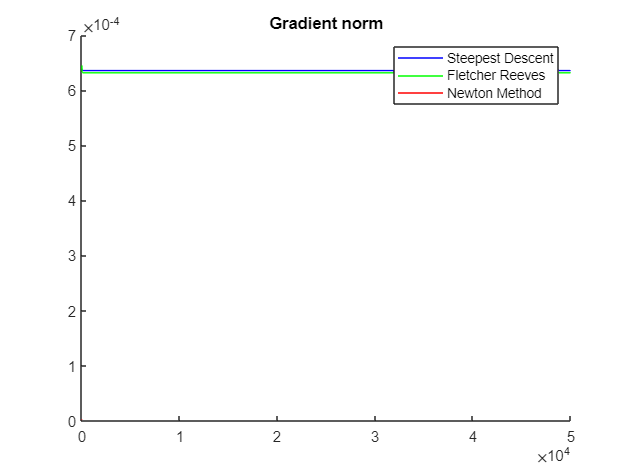

figure(1);
hold on;
title("Gradient norm")
plot(linspace(0,k_sd,k_sd), gfseq_sd, "b")
plot(linspace(0,k_fr,k_fr), gfseq_fr, "g")
plot(linspace(0,k_inm,k_inm), gfseq, "r")
legend(["Steepest Descent", "Fletcher Reeves", "Newton Method"])
hold off;

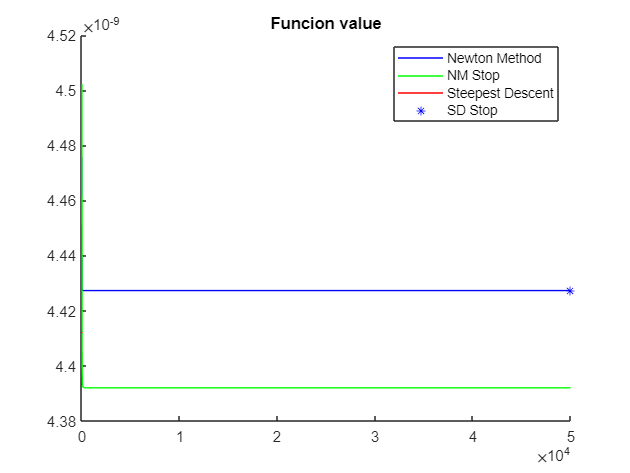

figure(2);
hold on;
title("Funcion value")
plot(linspace(0,k_sd,k_sd), fseq_sd, "b")
plot(linspace(0,k_fr,k_fr), fseq_fr, "g")
plot(linspace(0,k_inm,k_inm), fseq, "r")

plot(k_sd, fseq_sd(k_sd), "*b")
legend("Newton Method","NM Stop", "Steepest Descent", "SD Stop")
hold off;

% disp_int = [-1 1];
% 
% f1_meshgrid = @(X,Y)reshape(f([X(:),Y(:)]'),size(X));
% fcontour(f1_meshgrid, disp_int, 'Fill','on');
% hold on
% h = plot(xseq(1,:), xseq(2,:), '-*r', 'linewidth', 1, 'markersize', 5);
% hold off

% % creation of meshgrid for the contour-plot
% [X1, Y1] = meshgrid(linspace(-2, 2, 500), linspace(-2, 2, 500));
% 
% % computation of the values of f for each point of the mesh
% % Z1 = (1-X1).^2 + 100 * (Y1-X1.^2).^2;
% 
% % Plots
% 
% % simple plot
% fig1_n = figure();
% 
% % contour plot with curve levels for each point in xseq
% % [C1, ~] = contour(X1, Y1, Z1, [1, 10, 50, 100:1000:9000]);
% 
% hold on
% % plot of the points in xseq
% plot([x0(1) xseq(1, :)], [x0(2) xseq(2, :)], '-*', color="r")
% 
% hold off
% title('Inexact Newton')
